# ELEX7620 Lab 1

Name:  Mikhail, A01021119, set 6 S

Objective:  to simulate and measure a second order lowpass filter

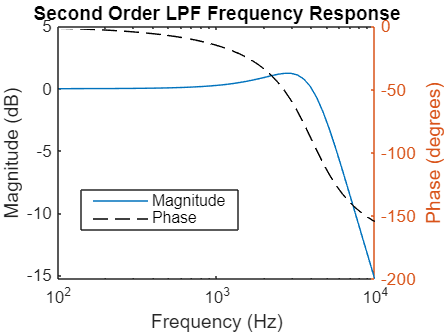

% Parameters for the filter
fc = 4000;        % Cutoff frequency in Hz
wc = 2 * pi * fc; % Cutoff frequency in rad/s
C1 = 100e-9;      % Capacitance C1 in Farads
C2 = 10e-9;       % Capacitance C2 in Farads
R1 = 3530.45;     % Resistance R1 in Ohms (calculated earlier)
R2 = 448.43;      % Resistance R2 in Ohms (calculated earlier)

% Coefficients of the transfer function
a0 = C1 * C2 * R1 * R2;               % Coefficient for s^2 term
a1 = C2 * (R1 + R2);                  % Coefficient for s term
a2 = 1;                               % Constant term
b0 = 1;                               % Numerator (low-pass, no s terms)

% Create the transfer function
b = [b0];                             % Numerator coefficients
a = [a0, a1, a2];                     % Denominator coefficients
H = tf(b, a);                         % Transfer function

% Plot the frequency response
freq = logspace(2, 4, 50);            % Frequency range from 100 Hz to 10 kHz
[mag, phase] = bode(H, 2 * pi * freq);% Get magnitude and phase response
mag_dB = 20 * log10(abs(mag(:,:)));   % Convert magnitude to decibels

figure(1)
clf
semilogx(freq, mag_dB)                % Plot magnitude in dB
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order LPF Frequency Response')
hold on
yyaxis right
semilogx(freq, phase(:,:), 'k--')     % Plot phase in degrees
ylabel('Phase (degrees)')
legend('Magnitude', 'Phase')
hold off

legend(["Magnitude", "Phase"], "Position", [0.1839 0.3052 0.3542, 0.1319])

## Calculate Component Values for Sallen Key Filter

## 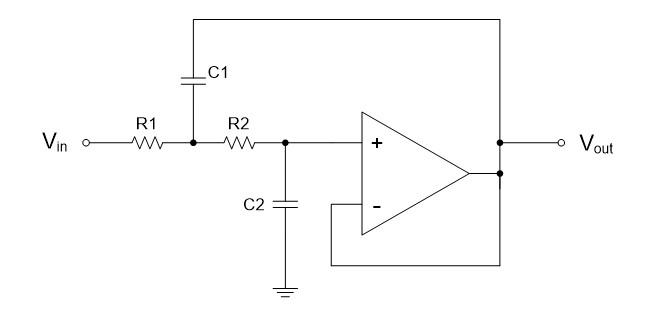

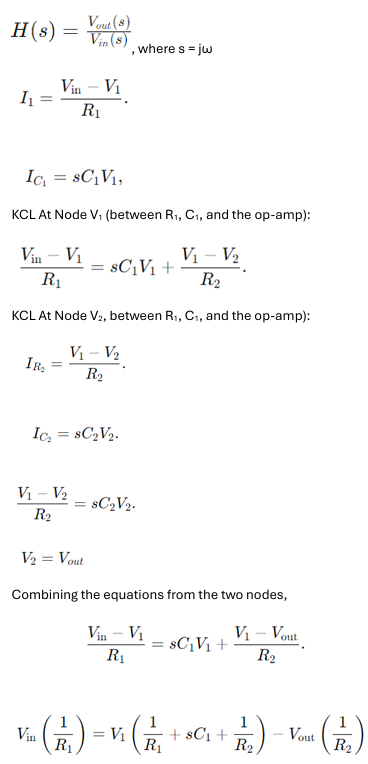

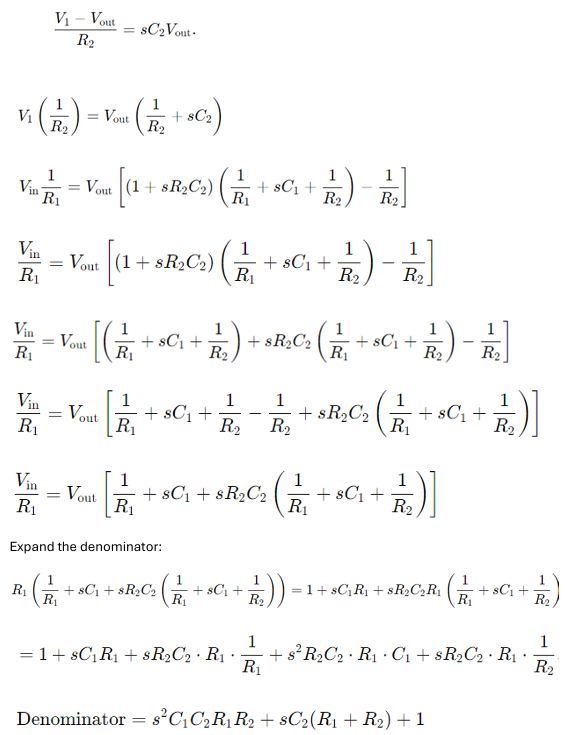

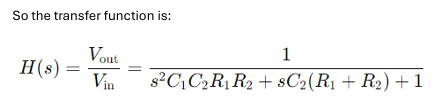

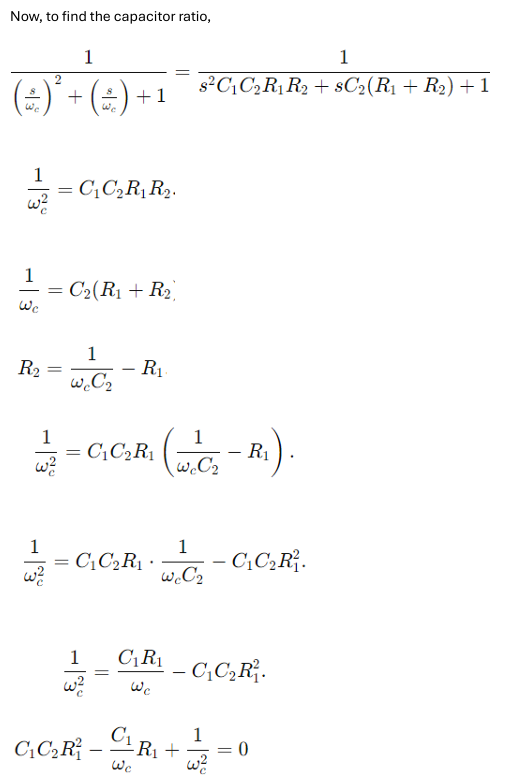

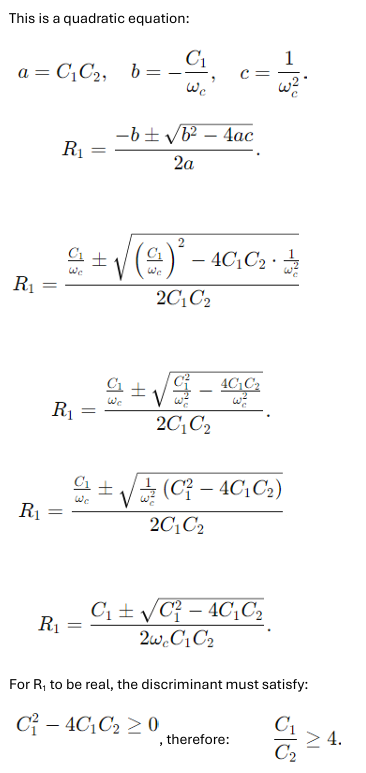

    It can be noted that if the two capacitors were equal, the discriminant would always be negative (complex),

    or else -3 * C^2 > 0, which doesn't make sense.

%Show your work for the steps below by inserting some documentation above or below this code block
%Specify the constraint for C2 / C1

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% the next two steps are found below:

%Set C1 and C2
%Calculate the values for R1 and R2


Let C1 = 100nF, 

and C2 = 10nF, with a ratio of capacitors 10:1.

Using a high ratio of C1/C2 (e.g., 10:1) is generally acceptable for a Sallen-Key low-pass filter. However, a very high ratio might:

- **Affect component selection:** Precision in the resistor values becomes critical to maintain the designed cutoff frequency and ensure stability.

- **Introduce gain peaking:** The filter may exhibit peaking near the cutoff frequency if the quality factor (Q) becomes too high, leading to undesired resonances.

A 10:1 ratio is on the higher side but should still work fine for most practical designs, as it avoids extreme Q factors.

This makes R1 and R2 the two following values:

% Given data
C1 = 100e-9; % 100 nF
C2 = 10e-9;  % 10 nF
fc = 4000;   % Cutoff frequency in Hz
omega_c = 2 * pi * fc;

% Coefficients of the quadratic equation
a = C1 * C2;
b = -C1 / omega_c;
c = 1 / omega_c^2;

% Solve the quadratic equation using roots
R1_solutions = roots([a, b, c]);
display(R1_solutions);

R1_solutions = 1.0e+03 *

    3.5304
    0.4484


So, R1 = 3.53kΩ, 

and R2 = 448.4Ω

This will likely be implemented with a 1kΩ and a 10kΩ potentiometer.

## LTSPICE Schematic

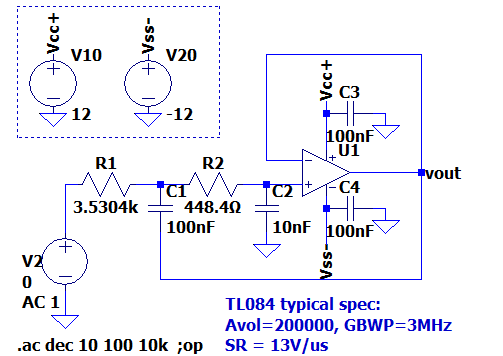

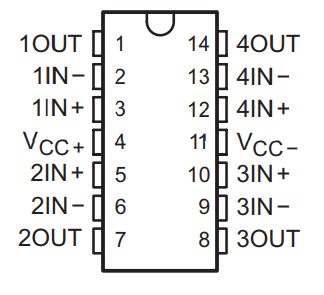

         TL084 Pin-out

## LTSPICE Simulation Results

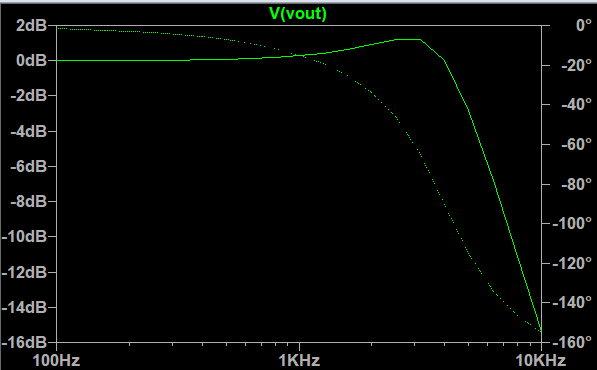

## Measurements

Record your measured data here and compare it against the theoretical results

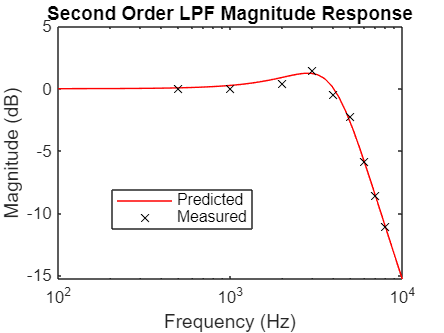

%Measured data; each triplet [f,vout,delay] is 
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [    [500, 1.00, 0],
                [1e3, 1.00, 26e-6],
                [2e3, 1.05, 41.4e-6],
                [3e3, 1.18, 43.3e-6],
                [4e3, 0.950, 52.7e-6],
                [5e3, 0.770, 58.1e-6],
                [6e3, 0.508, 55.2e-6],
                [7e3, 0.372, 50.8e-6],
                [8e3, 0.280, 45.8e-6]
           ];

%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 1;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);
meas_delay = measured(:,3);
meas_phase = (-1)*360*meas_delay.*meas_freq;

figure(2)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order LPF Magnitude Response')
legend('Predicted', 'Measured')

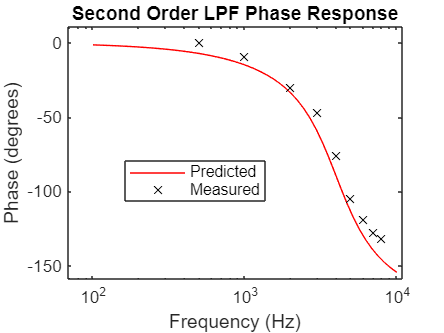


figure(3)
clf
semilogx(freq,phase(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('Second Order LPF Phase Response')
legend('Predicted', 'Measured')

xlim([6.8628e+01, 1.0877e+04])
ylim([-1.5903e+02, 1.0964e+01])
legend(["Predicted", "Measured"], "Position", [0.2824 0.3979 0.3156, 0.1180])